% I = imread("E:\Mgr\Systemy_wbudowane\proj\median1\hdmi_vga_zybo/RENKA_RAJSA_RESIZED.ppm");
I = imread("ryj_rajsa.jpg");
imwrite(I,"ryj_rajsa.ppm",'ppm')
I = imread("ryj_rajsa.ppm")

I = 720×1280×3 uint8 array
I(:,:,1) =

   194   194   194   194   194   194   194   194   191   191   192   192   193   193   192   193   191   191   192   192   193   193   194   194   196   194   195   199   200   196   195   197   197   197   197   197   198   198   198   198   201   201   202   202   202   201   201   201   202   202   203   203   204   204   204   203   204   204   204   204   204   204   204   204   203   203   204   205   204   204   203   202   203   203   203   203   203   203   203   203   203   202   201   202   204   206   205   204   204   204   203   203   203   203   203   203   201   201   201   201   202   202   203   203   205   206   207   203   204   208   210   208   206   206   206   206   206   206   206   206   205   205   205   205   205   204   204   203   203   203   203   203   203   204   204   204   205   205   205   205   205   205   205   205   205   205   205   205   205   205   204   204   206   206   206   206   205   205   205   205 


I = imresize(I,[64 64]);

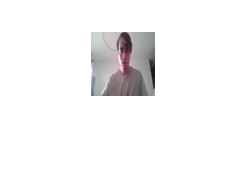

imshow(I)

size(I)

ans =     64    64     3


YCC = zeros([64, 64, 3]);

double_matrix = [0.299 0.587 0.114; -0.168736 -0.331264 0.5; 0.5 -0.418688 -0.081312]

double_matrix =     0.2990    0.5870    0.1140
   -0.1687   -0.3313    0.5000
    0.5000   -0.4187   -0.0813


const = [0; 128; 128]

const =      0
   128
   128


% for i = 1:64
%     for j = 1:64
%         R = I(i, j, 1);
%         G = I(i, j, 2);
%         B = I(i, j, 3);
%         %YCC(i,j,:) = double_matrix * double([R;G;B]) + const;
%         
%         % Normalize RGB values
%         R = R / 255.0;
%         G = G / 255.0;
%         B = B / 255.0;
%     
%         cmax = max([R, G, B]);
%         cmin = min([R, G, B]);
%         delta = cmax - cmin;
%     
%         % Compute the Hue
%         if delta == 0
%             hue = 0; % Undefined (achromatic)
%         elseif cmax == R
%             hue = 60 * mod((G - B) / delta, 6);
%         elseif cmax == G
%             hue = 60 * ((B - R) / delta + 2);
%         elseif cmax == B
%             hue = 60 * ((R - G) / delta + 4);
%         end
%     
%         % Compute the Saturation
%         if cmax == 0
%             saturation = 0;
%         else
%             saturation = delta / cmax;
%         end
%     
%         % Compute the Value
%         value = cmax;
%         YCC(i,j,:) = [hue, saturation, value];
%     end
% end
% YCC = uint8(YCC);

% Constants for fixed-point representation
numBits = 8; % Number of bits for fractional part
fractionScale = 2^numBits;

for i = 1:64
    for j = 1:64
        R = I(i, j, 1);
        G = I(i, j, 2);
        B = I(i, j, 3);
        
        % Normalize RGB values
        R = double(R) / 255.0;
        G = double(G) / 255.0;
        B = double(B) / 255.0;
    
        cmax = max([R, G, B]);
        cmin = min([R, G, B]);
        delta = cmax - cmin;
    
        % Compute the Hue
        if delta == 0
            hue = 0; % Undefined (achromatic)
        elseif cmax == R
            hue = mod(double(60) * ((G - B) / delta), double(6));
        elseif cmax == G
            hue = double(60) * ((B - R) / delta + double(2));
        elseif cmax == B
            hue = double(60) * ((R - G) / delta + double(4));
        end
    
        % Compute the Saturation
        if cmax == 0
            saturation = 0;
        else
            saturation = delta / cmax;
        end
    
        % Compute the Value
        value = cmax;
        
        % Convert to fixed-point representation
        hue_fixed = hue;
        saturation_fixed = uint8(saturation * fractionScale);
        value_fixed = uint8(value * fractionScale);
        %hue in range [0, 360]
        %sat, value in range [0, 1]
        YCC(i,j,:) = [hue_fixed, saturation_fixed, value_fixed];

    end
end
YCC

YCC = YCC(:,:,1) =

   240   240   240   240   240   240     0   240   240     0   240   240   240   240   240   240   240   240   240   210   192   180   180   180     3     5   192   180     1     6     2     3     6     0     0     0     0     0     0     0     0     0     4     4     0   240     0     0     0     0     4     0     4     4     0     0     0     0     0   210   225   220   220   228
   240     0   240   240   240   240   240   240   240     0     0   240   240   240   200   210   240   240   240   225   210   180   190     6     1     5     0   140     4     0     0     4     4     4     4     4     0     0   240   255     0     0     0     0     0   240     0     0     0     0     0     4     0     0     0     0     0     0     4     0   220   220   220   225
   240   240   255   240   240   240   240   240   240   240   240   240   240   210     1     3     0   240   240   216   180   200   187     0     5     4     2   100     6     3     3     6     4     4     4

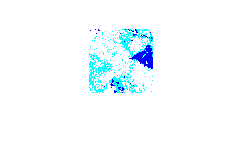

imshow(YCC)

%YCC = zeros([64, 64, 3]);

% double_matrix = [0.299 0.587 0.114; -0.168736 -0.331264 0.5; 0.5 -0.418688 -0.081312];
% m = fi(double_matrix, 1, 18, 17)
% const = [0; 128; 128];
% const = fi(const, 0, 8, 0)
% n = numerictype(1,9,0);
% for i = 1:64
%     for j = 1:64
%         R = fi(I(i, j, 1), 0, 8, 0);
%         G = fi(I(i, j, 2), 0, 8, 0);
%         B = fi(I(i, j, 3), 0, 8, 0);
%         Y = quantize(m(1, 1) * R, n) + quantize(m(1, 2) * G, n) + quantize(m(1, 3) * B, n);
%         Cb = quantize(m(2, 1) * R, n) + quantize(m(2, 2) * G, n) + quantize(m(2, 3) * B, n);
%         Cr = quantize(m(3, 1) * R, n) + quantize(m(3, 2) * G, n) + quantize(m(3, 3) * B, n);
%         YCC(i,j,:) = [Y; Cb; Cr] + const;
%     end
% end
% YCC = uint8(YCC);

imshow(YCC)

% hex(m)
 %hex(const)

% Ta = 80;
% Tb = 120;
% Tc = 120;
% Td = 170;
% binary = zeros(64, 64, 3);
% for row = 1:64
%     for col = 1:64
%         Cb = YCC(row, col, 2);
%         Cr = YCC(row, col, 3);
%         if (Cb > Ta && Cb < Tb && Cr > Tc && Cr < Td)
%             binary(row, col, :) = 255;
%         else
%             binary(row, col, :) = 0;
%         end
%     end
% end

% ThL = 80;
% Ts = 120;
% Tc = 120;
% Td = 170;
binary = zeros(64, 64, 3);
for row = 1:64
    for col = 1:64
        H = YCC(row, col, 1);
        S = YCC(row, col, 2);
        V = YCC(row, col, 3);
        % Fixed-point threshold values
        H_min = 0;
        H_max = 50;
        S_min = double(0.15) * fractionScale;
        S_max = double(0.7) * fractionScale;
        V_min = double(0.25) * fractionScale;
        V_max = double(1) * fractionScale;
        
        % Threshold condition
        if (H >= H_min && H <= H_max && S >= S_min && S <= S_max && V >= V_min && V <= V_max)
            binary(row, col, :) = 255;
            %H
            %H_max
        else
            binary(row, col, :) = 0;
        end
    end
end

m00 = 0;
m10 = 0;
m01 = 0;
for row = 1:64
    for col = 1:64
        m00 = m00 + (binary(row, col, 1)/255);
        m10 = m10 + ((row - 1)*(binary(row, col, 1)/255));
        m01 = m01 + ((col - 1)*(binary(row, col, 1)/255));
    end
end
m00

m00 = 1306

x_sc = round(m10/m00)

x_sc = 35

m10

m10 = 45499

y_sc = round(m01/m00)

y_sc = 35

m01

m01 = 45700

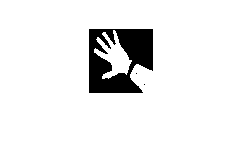

binary_2 = zeros(64, 64);
for row = 1:64
    for col = 1:64
        if (binary(row, col, 1) == 255)
            binary_2(row, col) = 1;
        else
            binary_2(row, col) = 0;
        end   
    end
end
med_img = medfilt2(binary_2, [5, 5]);
imshow(binary_2)

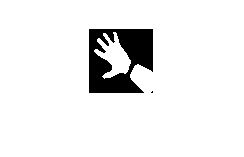

imshow(med_img)

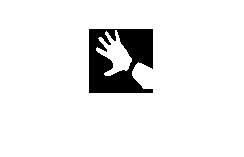

imshow('out_01.ppm')